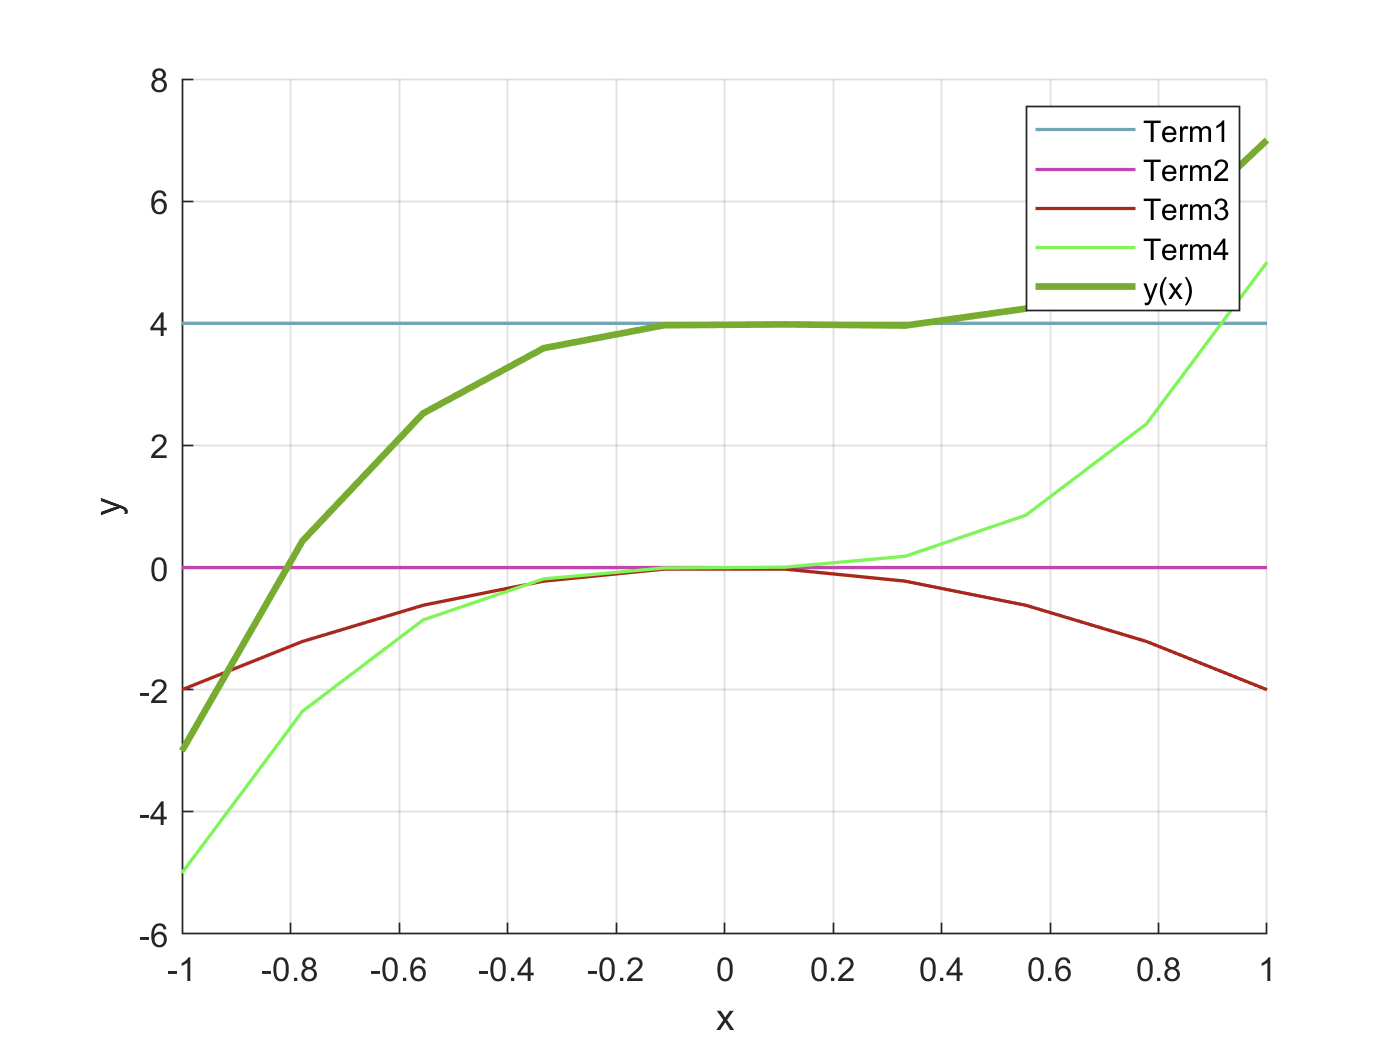

% Author: Shi Jie (Barney) Wei
% Date: 01/14/19

% Function that will calculate and plot any arbitrary polynomial function
% y(x)
% Input:
%   1) A row or column vector that contain the coefficients of the 
%      different terms of the polynomial
%   2) The range of x over which you would like the polynomial to be
%      calculated
% Output: value of the polynomial, y(x), at each value of x.

x_range = linspace(-1, 1, 10);
vec_coef = [4;0;-2;5];

y(length(x_range)) = 0;
term(length(vec_coef), length(x_range)) = 0;

% 1) Get polynomial values
for index1 = 1:length(x_range)
    for index2 = 1:length(vec_coef)
        term(index2, index1) = vec_coef(index2) * x_range(index1)^(index2-1);
    end
end
y = sum(term, 1);

% 2) Plot
figure
hold on
grid on
for index = 1:length(vec_coef)
    plot(x_range, term(index, :), 'color', rand(1, 3), 'LineWidth', 1, 'DisplayName', strcat('Term ', num2str(index)))
end
plot(x_range, y, 'LineWidth', 2, 'DisplayName', 'y(x)')
xlabel('x')
ylabel('y')
legend('show')